clear all;
rosshutdown; % shut down existing connection to ROS
ros_ip = "192.168.212.128";
rosinit(ros_ip,11311);

Initializing global node /matlab_global_node_83730 with NodeURI http://192.168.212.1:35295/ and MasterURI http://192.168.212.128:11311.


init

## here

% fabio
% build the neural network
net = build_network;

  YOLOv2Net with properties:

         Name: 'robocup'
       Anchor: []

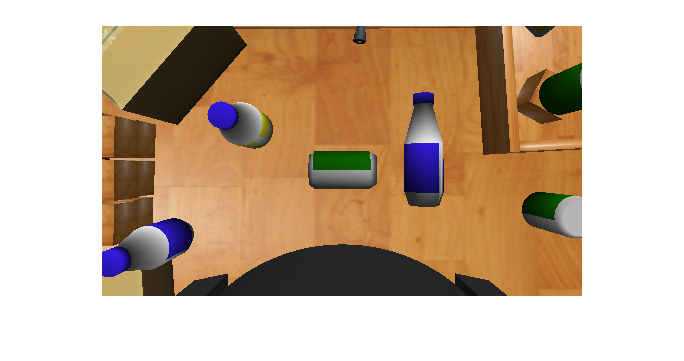

rgb=get_image('r');
imshow(rgb)

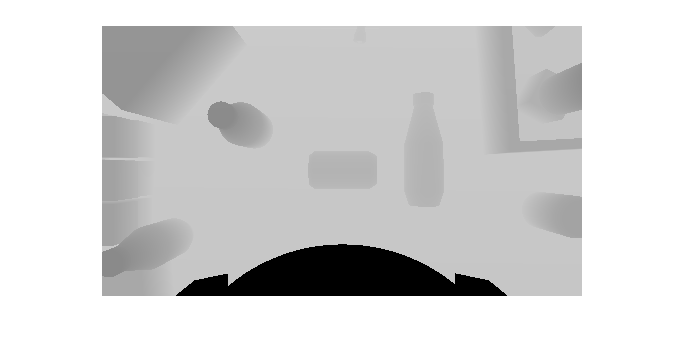

di=get_image('d');
imshow(di)

[prediction, bboxes, scores, labels] = classify(net,rgb);

Dot indexing is not supported for variables of this type.

Error in classify (line 2)
    [prediction, bboxes, scores, labels] = network.predict(image);

bboxes
imshow(prediction)